# GARD simulation following README steps B1–B6

% === B1) Create parameter structure ===
p = tgs_parameters_v10();      % load default parameters
p.GEN = 100;                  % number of generations
p.gen = 100;
p.NG = 100;
p.Kb = 0.00001;
p.Kf = 0.001;

for seed = 1:100
    p.seed = [seed, seed, seed];
    p.Beta = tgs_newbeta_v10(p);
    o = tgs_agard_v10(p, 1);
    save(sprintf('data/GARD_run_seed_%03d.mat', seed), 'p', 'o');
end

the assembly has died after 61 generations, R.I.P.
the assembly has died after 95 generations, R.I.P.


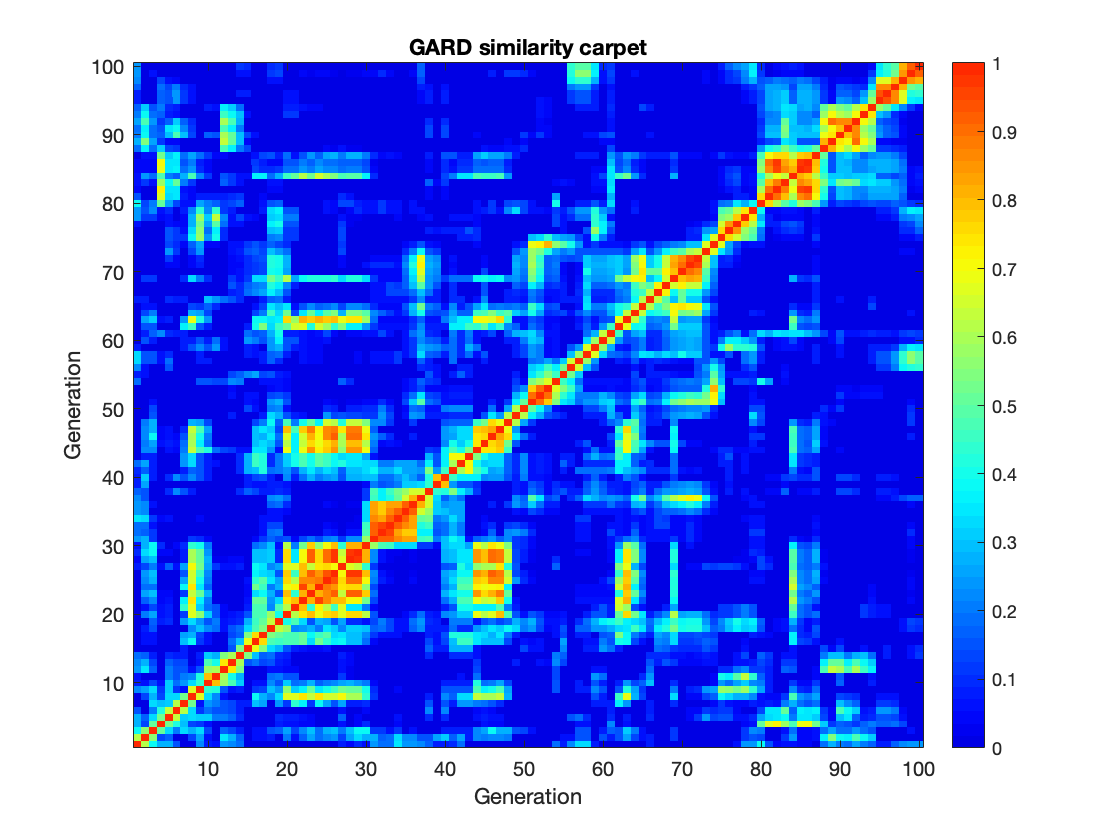

% === B5) Plot similarity carpet ===
figure;
c = tgs_carpet(o.trace);
title('GARD similarity carpet');
xlabel('Generation');
ylabel('Generation');

% === B6) Inspect output data structure ===

% (i) Compositional time series
disp('--- trace (composition time series) ---');

--- trace (composition time series) ---


disp(size(o.trace));   % NG x GEN

   100   100



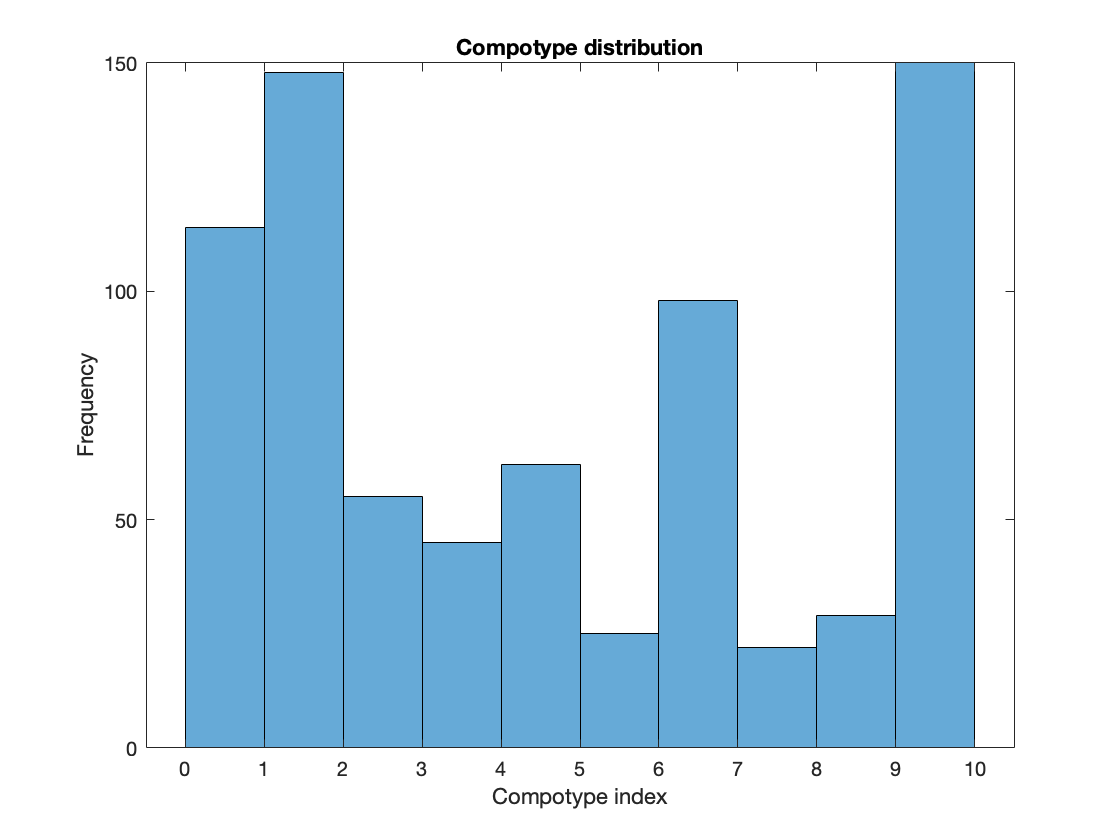


% (ii) Tags (compotype assignment per generation)
figure;
histogram(o.tags, 0:1:size(o.comps,2));
xlabel('Compotype index');
ylabel('Frequency');
title('Compotype distribution');


% (iii) Compotype compositions
disp('--- comps (compotype compositions) ---');

--- comps (compotype compositions) ---


disp(size(o.comps));

   100    10




% (iv) Carpet matrix dimensions
disp('--- carpet matrix c ---');

--- carpet matrix c ---


disp(size(c));

   100   100



## Optional: Save results

save('GARD_run_output.mat', 'p', 'o', 'c');